# Graph Neural Network for Heat Transfer Problems

This example trains a neural network to model the temperature $u(t=0.1, \mathbf{x})$ of a material at time $t=0.1$ for $\mathbf{x}$ in a 2 dimensional block with a cavity. The temperature $u$ evolves in time $t$ according to the heat equation 

$\rho c \frac{\partial u}{\partial t} - \nabla \cdot(k \nabla u) = Q$.

The heat equation is a partial differential equation (PDE). It models how the temperature $u$ evolves in time $t$ according to material properties such as the thermal conductivity $k$, the specific heat $c$ and mass density $\rho$, and internal heat sources $Q$. The temperature $u(t,\mathbf{x})$ depends on the time $t$ and the spatial coordinates $\mathbf{x}$. In general the heat equation holds for $\mathbf{x} \in \Omega$ where $\Omega$ is some geoemetric domain, for example the interior of a component. The temperature $u$ also depends also on initial conditions, the values of $u(t=0, \mathbf{x})$ for $\mathbf{x} \in \Omega$, and boundary conditions for $\mathbf{x} \in \partial \Omega$. Boundary conditions are often specified as Dirichlet boundary conditions for the temperature $u(t, \mathbf{x}) = f(t,\mathbf{x})$ for $\mathbf{x} \in \partial \Omega$ on the boundary, or as Neumann boundary conditions on the heat flux $\nabla_{\mathbf{n}} u(t,\mathbf{x})$ where $\nabla_{\mathbf{n}}$ is the directional derivative $\nabla \cdot \mathbf{n}$ in the direction of the normal $\mathbf{n}(\mathbf{x})$ to the boundary $\partial \Omega$ at $\mathbf{x}$.

In this example we set $\rho = 1$, $c = 1$, $k=1$, $Q = 0$ and consider a domain $\Omega$ which is rectangular with a smaller rectangular cavity as defined by `@crackg`. We use the thermal model of PDE toolbox to define and solve the heat equation for various initial and boundary conditions. We will fix a constant initial condition $u(t=0, \mathbf{x}) = u_0 \in \mathbb{R}$ and constant boundary conditions $u_L, v_R \in \mathbb{R}$ on specific edges of $\partial \Omega$. Here $u_L$ refers to the initial temperature on the left edge of the geometry, and $v_R$ refers to the heat flux on the right edge of the geometry. In this sense the we can consider the solutions as functions $u(t, \mathbf{x}, u_0, u_L, v_R)$. We consider a 2D problem $\mathbf{x} = (x,y)$. As such we can view the solution as a map $(t,x,y,u_0,u_L, v_R) \in \mathbb{R}^6 \rightarrow u(t,x,y,u_0,u_L,v_R) \in \mathbb{R}$. The remaining boundary edges get a homogeneous Neumann boundary condition, that is $\nabla_n u (t,\mathbf{x}) = 0$ for $\mathbf{x}$ on the remaining edges, which is interpreted as meaning no heat can escape through these edges.

In this example we will train a graph neural network to approximate the mapping $(t,x,y,u_0, u_L, v_R) \rightarrow u(t,x,y,u_0,u_L,v_R)$. In a graph neural network we group together all the coordinate samples $(x_i,y_i)$ into a graph $G$ where edges are $e$ are between nodes $(x_i, y_i), (x_j, y_j)$. When solving a PDE in PDE toolbox we have a graph defined by the finite element mesh.

## Load Initial and Boundary Conditions

The `Condition.xlsx` file contains values for initial temperature $u_0$, left edge temperature $u_L$ and right edge heat flux $v_R$. Preserve the variable names.

initialAndBoundaryConditions = readtable("Condition.xlsx",VariableNamingRule="preserve");

## Specify geometry and extract mesh graph

Use the PDE toolbox thermal model to define a meshed domain for the heat equation.

Create a thermal model. Recall $\rho = c = k = 1$, $Q = 0$, and we are using the `@crackg` geometry for $\Omega$. We use a `"transient"` model since we are considering the evolution of the temperature in time.

thermalmodel = createpde("thermal","transient");
geometryFromEdges(thermalmodel,@crackg);
thermalProperties(thermalmodel,...
    ThermalConductivity=1,...
    MassDensity=1,...
    SpecificHeat=1);
generateMesh(thermalmodel,GeometricOrder="linear");

Plot the mesh.

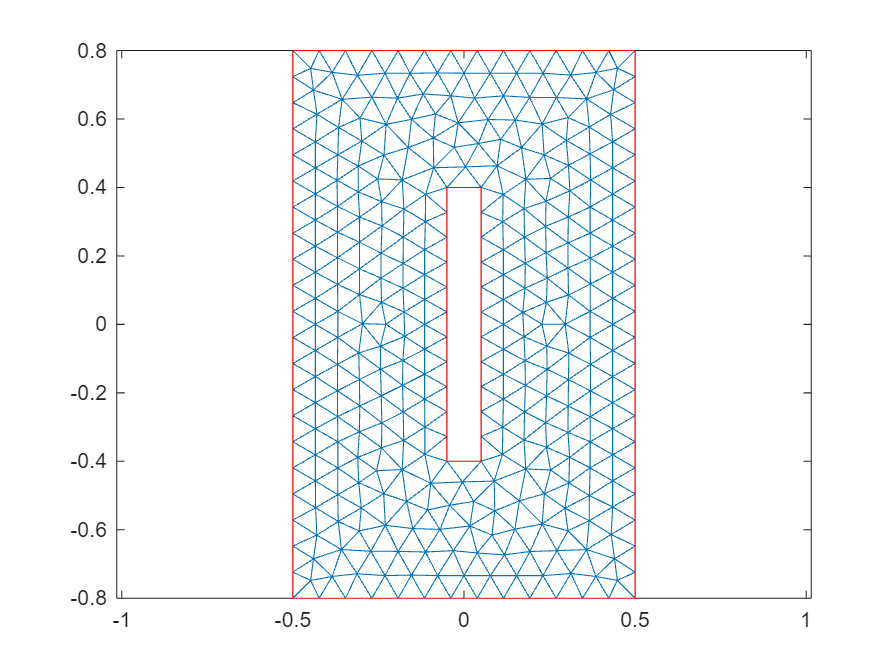

pdeplot(thermalmodel)

Get the mesh and create an adjacency matrix $A$. The adjacency matrix has element $a_{ij} = 1$if node $i$ and $j$ are connected, and $a_{ij} = 0$ otherwise. We include self connections $a_{ii} = 1$. The adjacency matrix is a useful computational tool for performing accumulation across connected nodes, for example a graph convolution.

mesh = thermalmodel.Mesh;
nodes = mesh.Nodes;
numNodes = size(nodes,2);
elements = mesh.Elements;
adjacency = zeros(numNodes);
for i = 1:size(elements,2)
    % The following logic specifies each node in an element is connected to
    % each other node in that element. That is true for linear geometric
    % order meshes, but not quadratic meshes.
    nodesForElement = elements(:,i);
    for node = nodesForElement
        adjacency(nodesForElement,node) = 1;
    end
end

## Solve the PDE

Solve the PDE for various initial and boundary conditions.

Specify times to output the solution of the PDE.

solutionTimes = 0:0.01:0.1;

Solve the PDE in a loop. For speed we'll consider only a handful of cases for now.

initialAndBoundaryConditions = initialAndBoundaryConditions(1:240,:);
numObservations = height(initialAndBoundaryConditions);
initialCondition = initialAndBoundaryConditions.("Initial Condition");
dirichletBoundary = initialAndBoundaryConditions.E6_Temperature;
neumannBoundary = initialAndBoundaryConditions.E1_HeatFlux;
if ~isfile('data.mat')
    parfor i = 1:numObservations
        % Set initial condition
        thermalIC(thermalmodel,initialCondition(i));
        % Set left edge boundary condition
        thermalBC(thermalmodel, Edge=6, Temperature = dirichletBoundary(i));
        % Set right edge boundary condition.
        thermalBC(thermalmodel,Edge = 1, HeatFlux = neumannBoundary(i));
        % Solve the PDE
        solution{i} = solve(thermalmodel,solutionTimes);
    end
    save('data.mat',"solution")
else
    load('data.mat')
end

## Visualize a solution

Use `pdeplot` to plot a heat map of one of the solutions at time $t=0.1$.

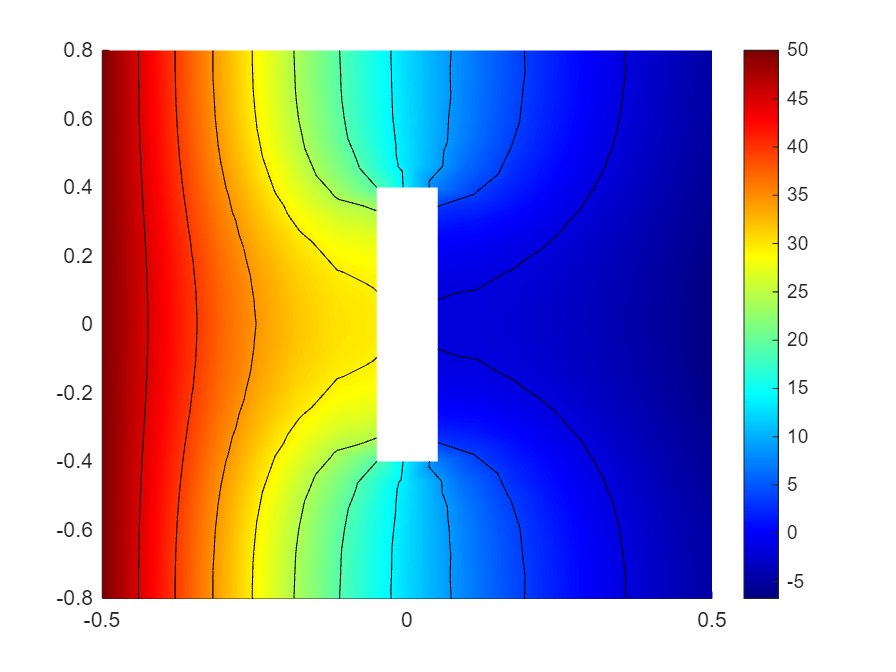

figure
pdeplot(thermalmodel,XYData=solution{1}.Temperature(:,end),Contour="on",ColorMap="jet");

## Create input and output features

The input to the model is the graph $G_{u_0, u_L, v_R}$ consisting the mesh nodes, their connections, and node features such as coordinates $(x,y)$ and initial and boundary conditions $(u_0, u_L, v_R)$.

nodeCoordinates = permute(nodes,[3,2,1]);
% repeat nodes over various observations of initial and boundary conditon
nodeCoordinates = repmat(nodeCoordinates,[numObservations,1,1]);
% Repeat initial conditions and boundary conditions over node dimension
nodeIC = repmat(initialCondition,[1,numNodes,1]);
nodeDBC = repmat(dirichletBoundary,[1,numNodes,1]);
nodeNBC = repmat(neumannBoundary,[1,numNodes,1]);
input = cat(3,nodeCoordinates,nodeIC,nodeDBC,nodeNBC);
input = dlarray(input);
% Permute the input to features x nodes xbatch
input = permute(input,[3,2,1]);

The output targets are the temperatures at the coordinates for the given solution.

targets = zeros(1,numNodes,numObservations);
for i = 1:numObservations
    targets(1,:,i) = solution{i}.Temperature(:,end);
end
targets = dlarray(targets);

## Define graph neural network

A graph neural network takes the input features `input`, the `adjacency` matrix, and computes a graph convolution over the input features. It uses a weight matrix to accumulate information from neighbouring nodes onto each node. We use an initial node embedding into a latent dimension to make it easier to create residual connections in the latent dimension, then use a decoder model to project the GNN output back to the target dimension.

% set to use GPU if it's available. 
% If you don't want to use it, edit this like gpuUse = false;
gpuUse = canUseGPU;
% dimention of latent channel
latentDim = 20;
% number of layer
numGNNLayers = 2;
inputDim = size(input,1);
% Set the initial weight of the model
params.Embedding.W = initializeGlorot([latentDim,inputDim]);
params.Embedding.b = zeros(latentDim,1);
for i = 1:numGNNLayers
    params.("GNN_"+i).W = initializeGlorot([latentDim,latentDim]);
    params.("GNN_"+i).b = zeros([latentDim,1]);
end
params.Decoder.W = initializeGlorot([1,latentDim]);
params.Decoder.b = zeros(1,1);
params = dlupdate(@dlarray,params);
% a Variable used for normalization
inputRescale = dlarray([1;1;max(input(3:5,:,:),[],[2,3])]);
test = gnn(params,input,adjacency,numGNNLayers,inputRescale);

## Train the GNN

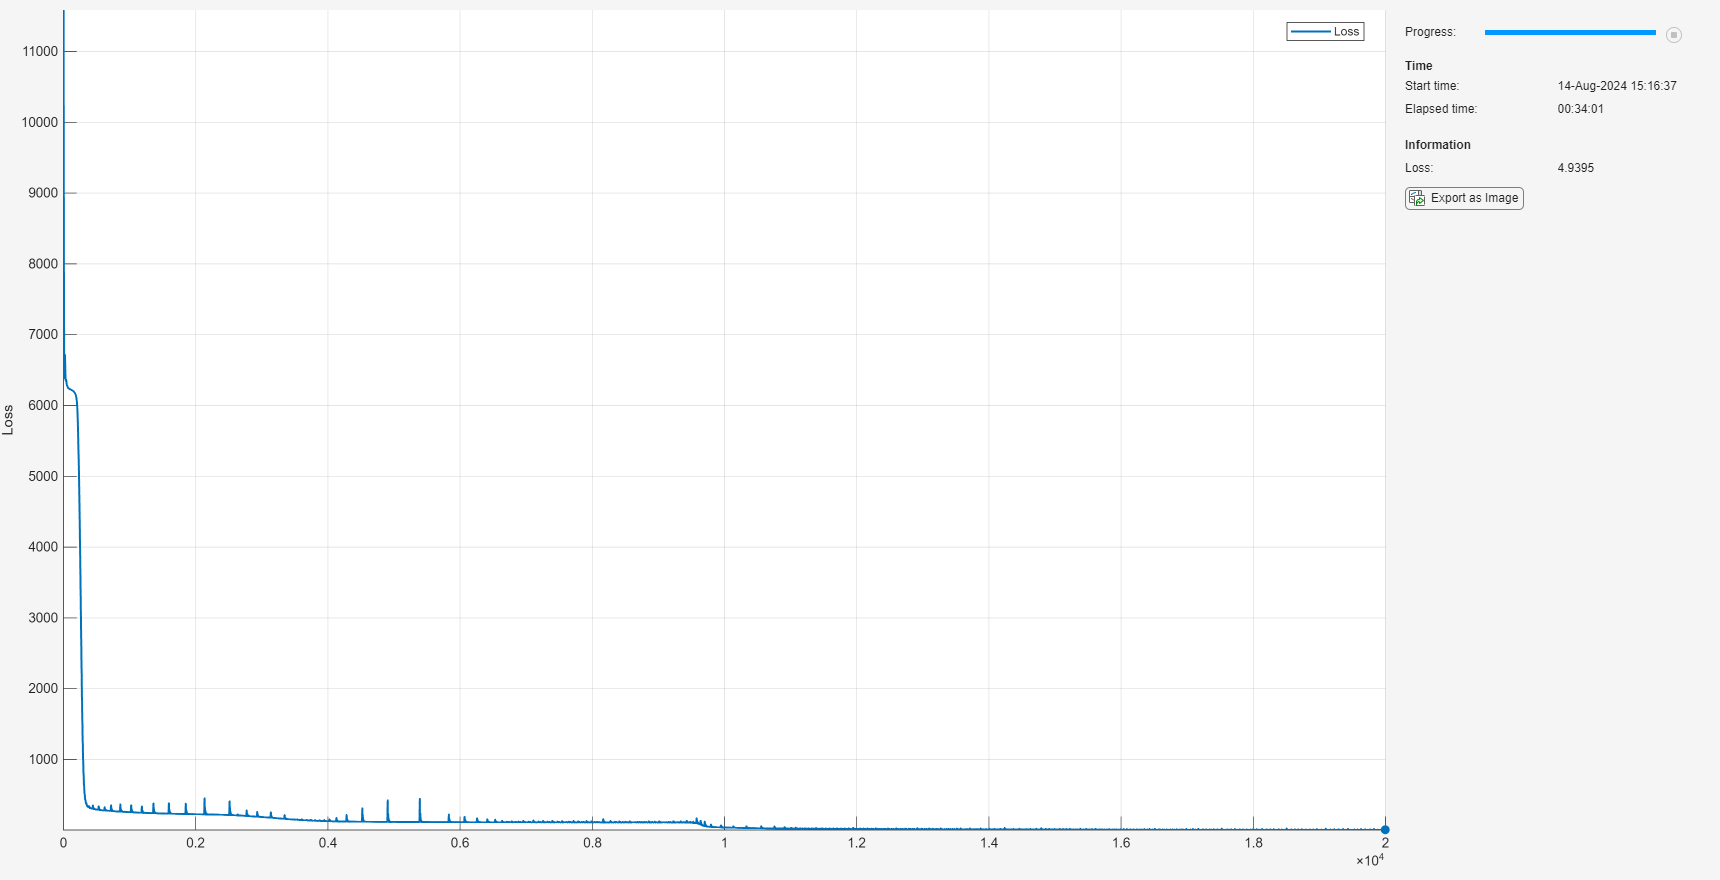

% Set whether to train or not. If not, set it to false.
training =true;
% Set the training options.
lr = 1e-3;
maxEpochs = 20000;
avgG = [];
avgSqG = [];
mtr = trainingProgressMonitor("Metrics","Loss","Info","Loss");
lossfcn = dlaccelerate(@modelLoss);
clearCache(lossfcn);
if gpuUse == true
    params = dlupdate(@gpuArray,params);
    adjacency = gpuArray(adjacency);
    input = gpuArray(input);
    targets = gpuArray(targets);
end

if training==true
    for epoch = 1:maxEpochs
        [loss,grad] = dlfeval(lossfcn,params,input,adjacency,numGNNLayers,inputRescale,targets);
        mtr.recordMetrics(epoch,Loss = loss);
        mtr.updateInfo(Loss=loss);
        mtr.Progress = 100*(epoch/maxEpochs);
        [params,avgG,avgSqG] = adamupdate(params,grad,avgG,avgSqG,epoch,lr);
    end
    save("params.mat","params")
else
    load("params_pre.mat");
end

## Test on unseen initial and boundary condition

Use the last initial and boundary conditions to test the model.

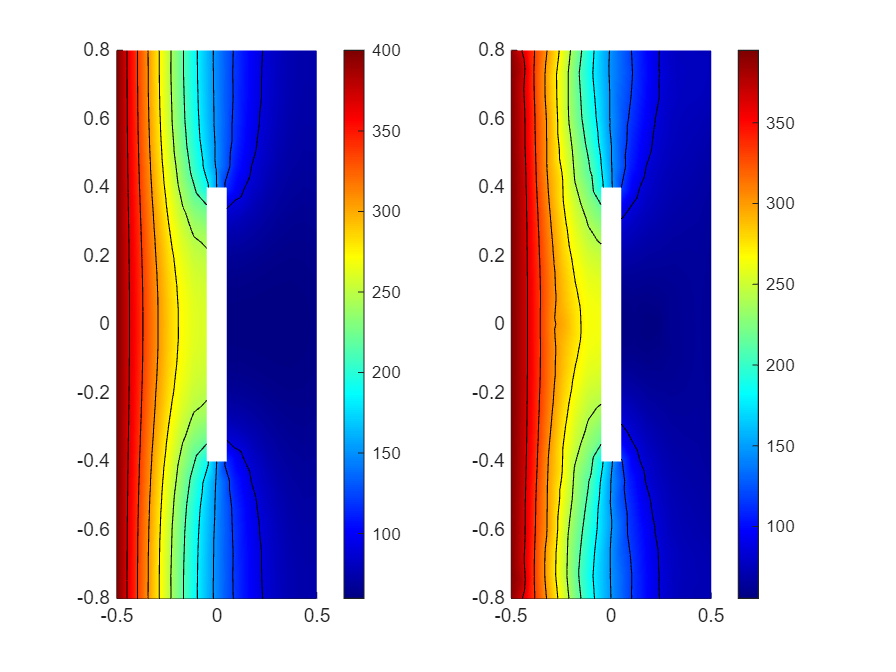

thermalIC(thermalmodel,initialCondition(end));
thermalBC(thermalmodel,Edge=6,Temperature=dirichletBoundary(end));
thermalBC(thermalmodel,Edge=1,HeatFlux=neumannBoundary(end));
result = solve(thermalmodel,[0,0.1]);
x = thermalmodel.Mesh.Nodes.';
numNodes = size(x,1);
upred = gnn(params,input,adjacency,numGNNLayers,inputRescale);
figure;
subplot(1,2,1);
pdeplot(thermalmodel,XYData=result.Temperature(:,end),Contour="on",ColorMap="jet");
subplot(1,2,2);
pdeplot(thermalmodel,XYData=extractdata(upred(1,:,end)),Contour="on",ColorMap="jet");

## Define loss function

% The function modelLoss takes network parameters, a mini-batch of input data, an input for rescale and target values, 
% and returns the loss values, the gradients of the loss values with respect to the learnable parameters in the networks.

function [loss,grad] = modelLoss(params,input,adjacency,numGNNLayers,inputRescale,target)
    prediction = gnn(params,input,adjacency,numGNNLayers,inputRescale);
    loss = l2loss(prediction,target,DataFormat="CUB",NormalizationFactor="all-elements");
    if nargout>1
        grad = dlgradient(loss,params);
    end
end

function u = gnn(params, input, adjacency, numGNNLayers, inputRescale)
    % normalize adjacency
    deg = sum(adjacency,2);
    factor = 1./sqrt(deg);
    adjacency = diag(factor)*adjacency*diag(factor);
    % Store left boundary temperature
    uL = input(4,:,:);
    % Rescale
    u = input./inputRescale;
    % % Initial embedding
    u = pagemtimes(params.Embedding.W, input) + params.Embedding.b;
    u = tanh(u);
    for i = 1:numGNNLayers
        % Compute latent features
        v = pagemtimes(params.("GNN_"+i).W,u) + params.("GNN_"+i).b;
        % agrregate over neighbours
        v = pagemtimes(v,adjacency);
        % Add nonlinearity
        v = tanh(v);
        % Add residual
        %u = u+v;
        u = v; % no residual for now
    end
    % Project
    u = pagemtimes(params.Decoder.W, u) + params.Decoder.b;
    % Sigmoid and rescale
    u = sigmoid(u);
    u = u.*uL;
end

function w = initializeGlorot(sz)
    scale = 2*sqrt(6/(sz(1)+sz(2)));
    w = scale*(rand(sz)-0.5);
end

Copyright (c) 2024, The MathWorks, Inc.